clc;clear;

main_dir = ['/storage08/shuchen/SimulationData/settingSSoS/' ...
    'n500-k10-p_in2btw4-p_out1btw1/' ...
    'r_time0-time_horizon2-r_subject0-num_subjects8/']

main_dir = '/storage08/shuchen/SimulationData/settingSSoS/n500-k10-p_in2btw4-p_out1btw1/r_time0-time_horizon2-r_subject2-num_subjects8/'

% main_dir = 'D:\OneDrive\OneDrive - UW-Madison\Sunduz\SimulationData\settingSSoT\n100-k2-p_in2btw25-p_out1btw1';
% main_dir = 'C:\OneDrive\OneDrive - UW-Madison\Sunduz\SimulationData\settingSSoT\n100-k2-p_in2btw25-p_out1btw1';

samplesTotal = 100;

% load data for the /0/ file
disp(main_dir);

/storage08/shuchen/SimulationData/settingSSoS/n500-k10-p_in2btw4-p_out1btw1/r_time0-time_horizon2-r_subject2-num_subjects8/


sub_dir = dir(main_dir);
n_rep = 100;
aris_max = zeros([n_rep,1]);
aris_mean = zeros([n_rep,1]);
aris_med = zeros([n_rep,1]);
i = 3;
i_rep = i-3;
path = [main_dir, sub_dir(i).name];
K_edges = 0:15:240;

ari_i = load([path,'/aris_ori.mat']).aris;
z = load([path,'/z_ori.mat']).zS;
size_z = size(z);
K_ori = zeros([size_z(1), size_z(2), size_z(4)]);

% find the number of communities (K) for each s,t, and sample
for s = 1:size_z(1)
    disp(s);
    for t = 1:size_z(2)
        for sample = 1:size_z(4)
            K_ori(s,t,sample) = max(unique(z(s,t,:,sample)));
        end
    end
end

     1

     2

     3

     4

     5

     6

     7

     8



ans = -0.3333

%
K_st = mean(K_ori, [1,2]);  % K_st: mean of K among subjects and time
K_st = reshape(K_st, 100, 1);
K_mask = K_st<=12 & K_st>=8;
sum((K_st<=12 & K_st>=8))

ans = 5


ari = mean(ari_i,[1,2]);
ari = reshape(ari, 100,1);
ari_good = ari(K_mask);

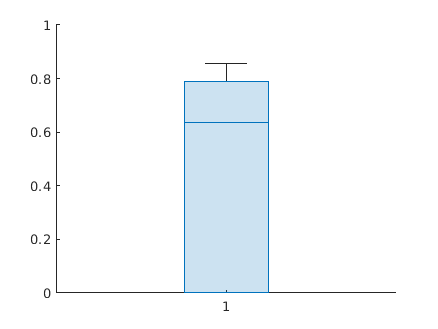

figure
boxchart(ari_good)

median(ari_good)

ans = 0.6379

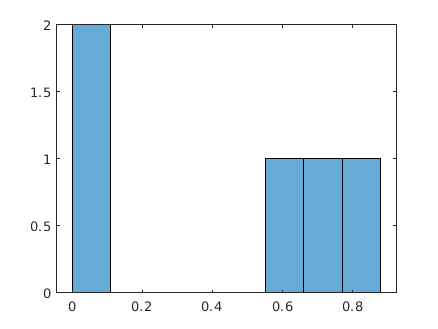

histogram(ari_good,8)

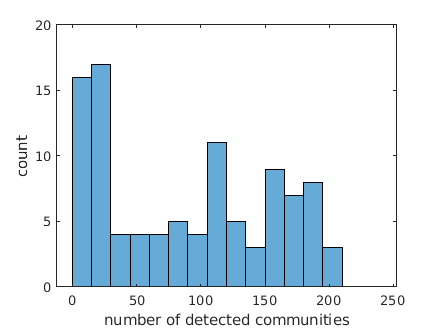

figure
h = histogram(K_st,K_edges);
xlabel("number of detected communities")
ylabel("count")

h.BinCounts

ans =     16    17     4     4     4     5     4    11     5     3     9     7     8     3     0     0


[counts,~] = histcounts(K_st, K_edges);
[~, i_freq] = max(counts);
K_mask = K_st>= K_edges(i_freq) & K_st<K_edges(i_freq+1);

ari = mean(ari_i,[1,2]);
ari = reshape(ari, 100,1);
ari_freq = ari(K_mask);

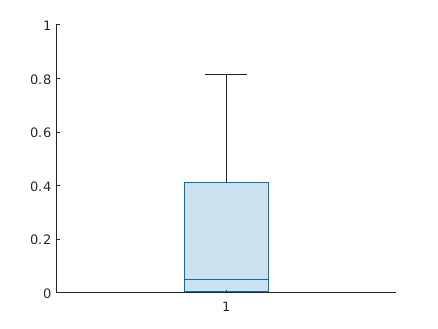

figure
boxchart(ari_freq)

median(ari_freq)

ans = 0.0489

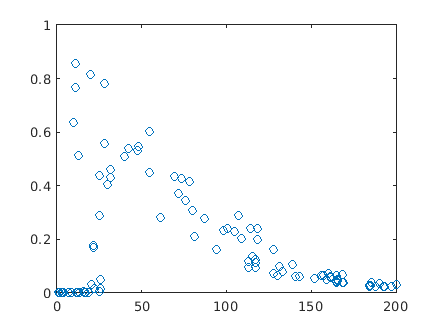

plot(K_st, ari, "o")

% ari_sample = mean(ari_i,[1,2]);
% ari_sample = reshape(ari_sample, samplesTotal, 1);

% aris_max(i_rep+1) = max(ari_sample);
% aris_mean(i_rep+1) = mean(ari_sample); 
% aris_med(i_rep+1) = median(ari_sample);

disp(main_dir);

/storage08/shuchen/SimulationData/settingSSoS/n500-k10-p_in2btw4-p_out1btw1/r_time0-time_horizon4-r_subject5-num_subjects8/


sub_dir = dir(main_dir);
n_rep = 100;
aris_max = zeros([n_rep,1]);
aris_mean = zeros([n_rep,1]);
aris_med = zeros([n_rep,1]);
for i = 3:(n_rep+2)
    i_rep = i-3;
    path = [main_dir, sub_dir(i).name];
    ari_i = load([path,'/aris_ori.mat']).aris;
    ari_sample = mean(ari_i,[1,2]);
    ari_sample = reshape(ari_sample, samplesTotal, 1);
    
    aris_max(i_rep+1) = max(ari_sample);
    aris_mean(i_rep+1) = mean(ari_sample); 
    aris_med(i_rep+1) = median(ari_sample);
end

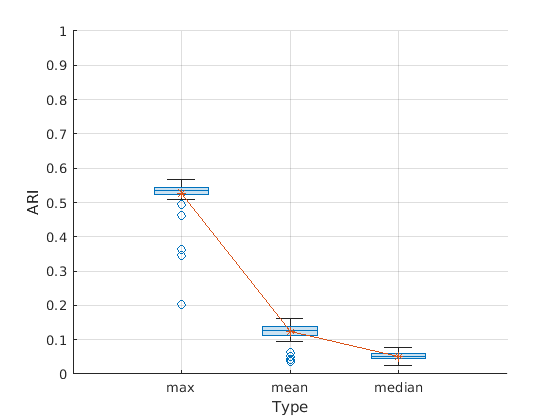

aris3 = [aris_max, aris_mean, aris_med];

figure
boxchart(aris3);         
hold on
grid on
plot(mean(aris3,1),'-*');

xlabel("Type");
ylabel("ARI");
ylim([0,1]);
xticklabels(["max","mean","median"]);